### Step 0 加载并绘制原始mri图像

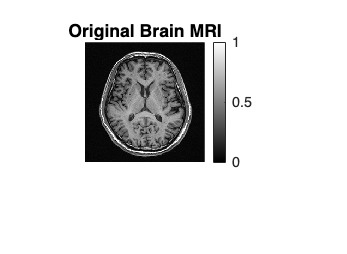

data = load('../data/Lab4_2025_MRI.mat');
variableNames = fieldnames(data);
mriData = data.(variableNames{1}); 
mriData = mat2gray(mriData);

figure;
imshow(mriData, []);
colormap gray;
colorbar;
title('Original Brain MRI');

## Project 2 denoise

### **Step 1 中值滤波器**

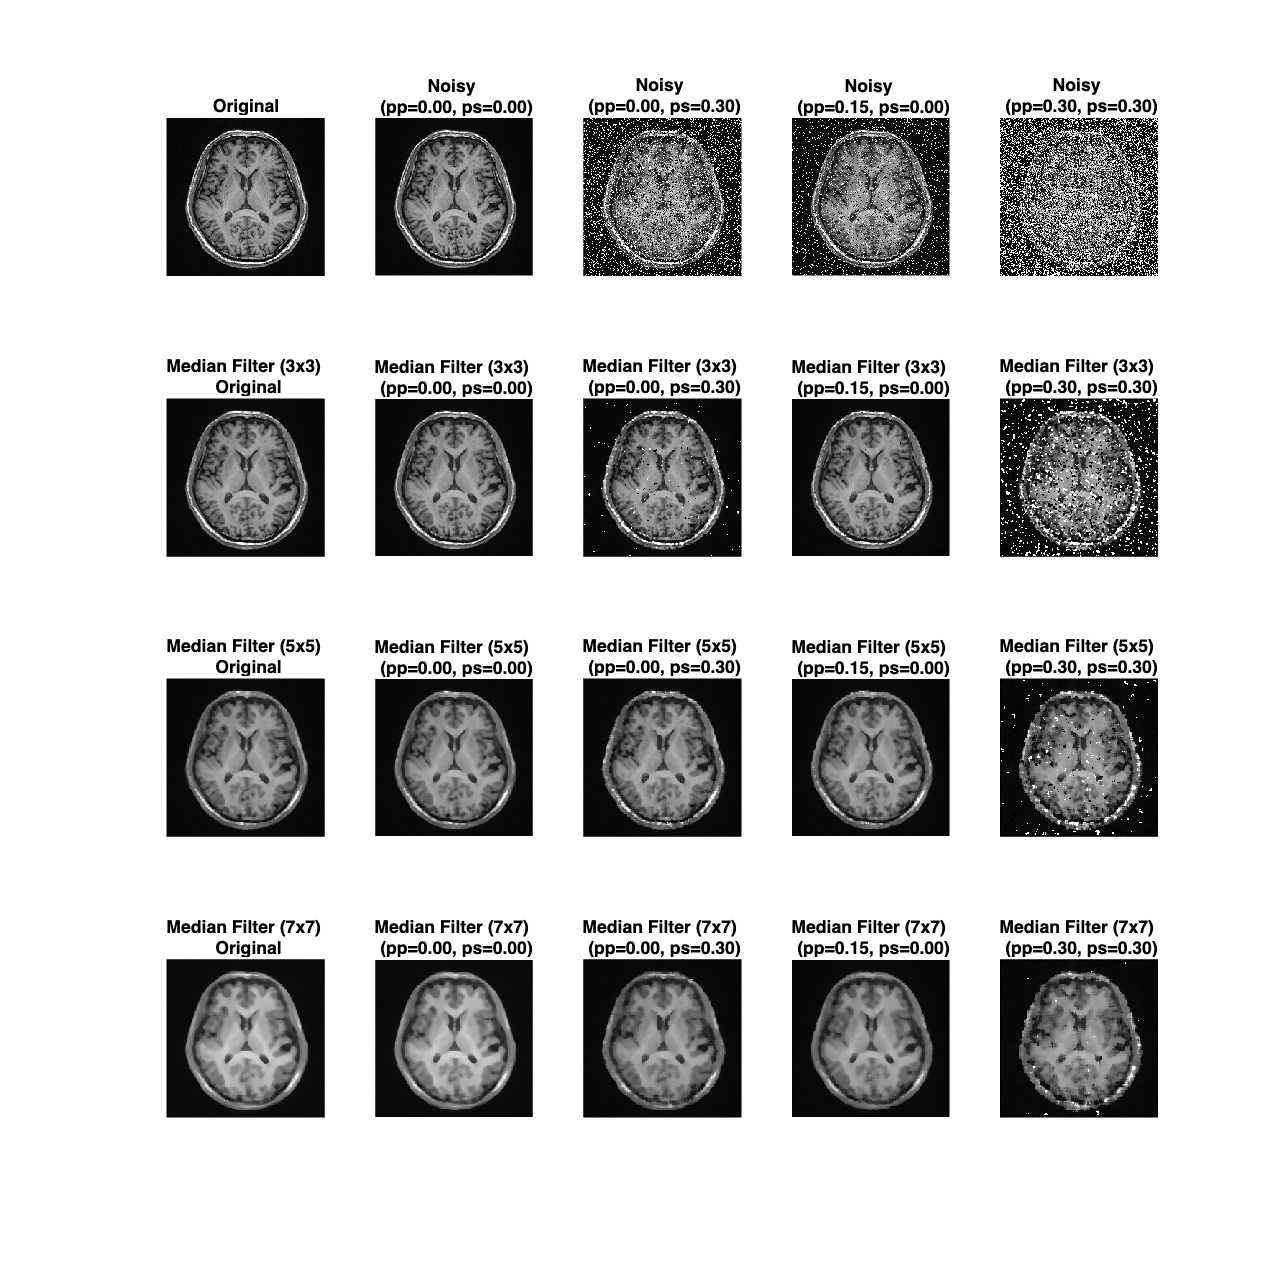

selected_combinations = [1 1; 1 3; 2 1; 3 3]; 
kernel_sizes = [3, 5, 7];

% 可视化结果的图
figure('Position', [100, 100, 1500, 1500]);

% 第一行：原始图 + 4种不同取值pp、ps的图
subplot(4, 5, 1);
imshow(mriData, []);
title('Original');
for k = 1:4
    i = selected_combinations(k, 1);
    j = selected_combinations(k, 2);
    subplot(4, 5, k + 1);
    imshow(noisyImages_salt_pepper{i,j}, []);
    title(sprintf('Noisy \n (pp=%.2f, ps=%.2f)', pps(i), pss(j)));
end

% 第二行：中值滤波器kernel size = 3*3的滤波结果
denoised_median_3_original = medfilt2(mriData, [3 3]);
subplot(4, 5, 6);
imshow(denoised_median_3_original, []);
title(sprintf('Median Filter (3x3) \n Original'));
for k = 1:4
    i = selected_combinations(k, 1);
    j = selected_combinations(k, 2);
    noisy = noisyImages_salt_pepper{i,j};
    denoised_median_3 = medfilt2(noisy, [3 3]);
    subplot(4, 5, k + 6);
    imshow(denoised_median_3, []);
    title(sprintf('Median Filter (3x3) \n (pp=%.2f, ps=%.2f)', pps(i), pss(j)));
end

% 第三行：中值滤波器kernel size = 5*5的滤波结果
denoised_median_5_original = medfilt2(mriData, [5 5]);
subplot(4, 5, 11);
imshow(denoised_median_5_original, []);
title(sprintf('Median Filter (5x5) \n Original'));
for k = 1:4
    i = selected_combinations(k, 1);
    j = selected_combinations(k, 2);
    noisy = noisyImages_salt_pepper{i,j};
    denoised_median_5 = medfilt2(noisy, [5 5]);
    subplot(4, 5, k + 11);
    imshow(denoised_median_5, []);
    title(sprintf('Median Filter (5x5) \n (pp=%.2f, ps=%.2f)', pps(i), pss(j)));
end

% 第四行：中值滤波器kernel size = 7*7的滤波结果
denoised_median_7_original = medfilt2(mriData, [7 7]);
subplot(4, 5, 16);
imshow(denoised_median_7_original, []);
title(sprintf('Median Filter (7x7) \n Original'));
for k = 1:4
    i = selected_combinations(k, 1);
    j = selected_combinations(k, 2);
    noisy = noisyImages_salt_pepper{i,j};
    denoised_median_7 = medfilt2(noisy, [7 7]);
    subplot(4, 5, k + 16);
    imshow(denoised_median_7, []);
    title(sprintf('Median Filter (7x7) \n (pp=%.2f, ps=%.2f)', pps(i), pss(j)));
end

### **Step 2 **`调和平均滤波器`

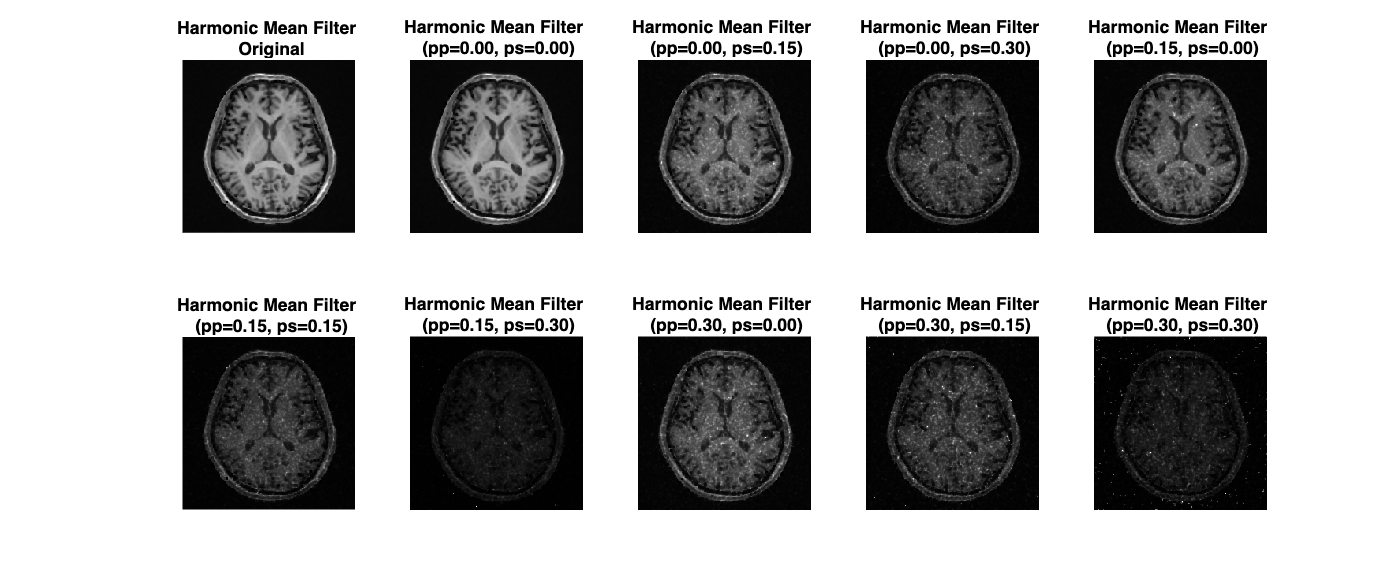

function output = harmonic_mean_filter(input, window_size)
    [rows, cols] = size(input);
    output = zeros(rows, cols);
    
    pad_size = floor(window_size / 2);
    padded_input = padarray(input, [pad_size pad_size], 'symmetric');
    
    for i = 1:rows
        for j = 1:cols
            window = padded_input(i:i+2*pad_size, j:j+2*pad_size);
            non_zero_window = window(window > 0);
            if ~isempty(non_zero_window)
                output(i,j) = window_size^2 / sum(1./non_zero_window);
            else
                output(i,j) = 0;
            end
        end
    end
end

% 可视化结果的图
figure('Position', [100, 100, 1200, 500]);

% 对原图进行调和平均滤波
denoised_harmonic_original = harmonic_mean_filter(mriData, 3);
subplot(2, 5, 1);
imshow(denoised_harmonic_original, []);
title(sprintf('Harmonic Mean Filter \n Original'));

im_num = 2;
for i = 1:3
    for j = 1:3
        noisy = noisyImages_salt_pepper{i,j};
        denoised_harmonic = harmonic_mean_filter(noisy, 3);
        subplot(2, 5, im_num);
        imshow(denoised_harmonic, []);
        title(sprintf('Harmonic Mean Filter \n (pp=%.2f, ps=%.2f)', pps(i), pss(j)));
        im_num = im_num + 1;
    end
end

### **Step 3 **`自适应中值滤波`

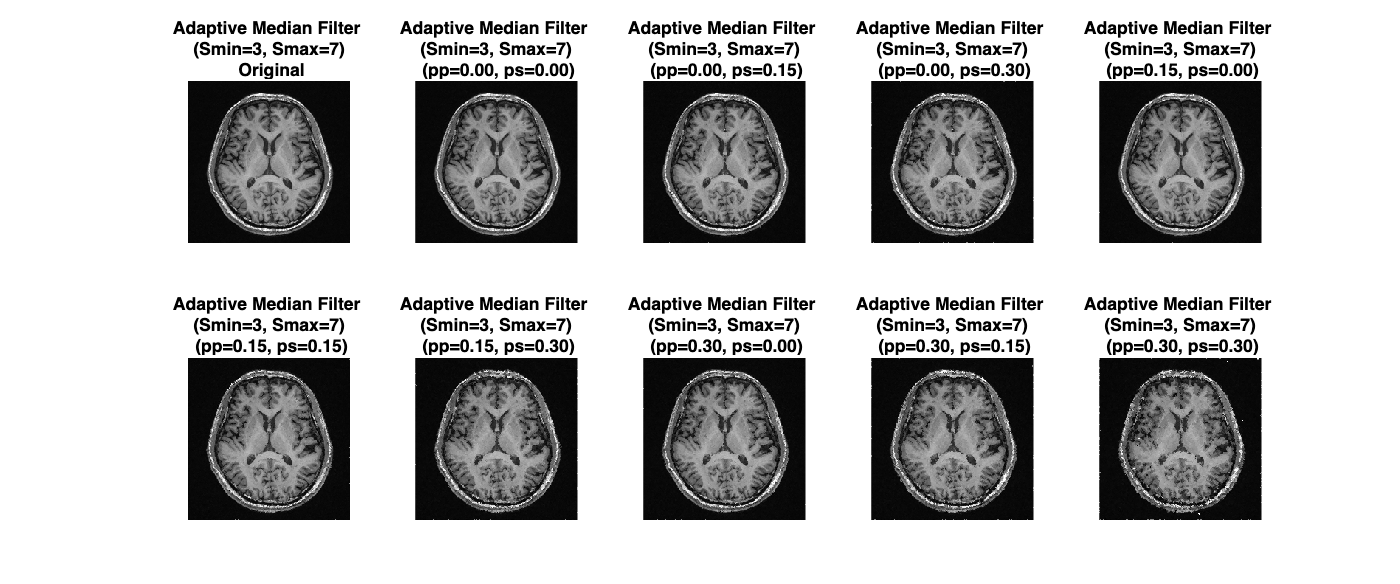

% 定义自适应中值滤波函数
function output = adaptive_median_filter(input, Smin, Smax)
    % 确保输入图像是双精度类型
    input = double(input);
    [rows, cols] = size(input);
    output = zeros(rows, cols);
    
    for i = 1:rows
        for j = 1:cols
            % 调用自适应中值滤波核心函数
            output(i,j) = adaptive_median(input, i, j, Smin, Smax);
        end
    end
end

function zxy = adaptive_median(input, x, y, Smin, Smax)
    % 确保输入图像是双精度类型
    input = double(input);
    S = Smin;
    while S <= Smax
        halfS = floor(S / 2);
        x1 = max(x - halfS, 1);
        x2 = min(x + halfS, size(input, 1));
        y1 = max(y - halfS, 1);
        y2 = min(y + halfS, size(input, 2));
        window = input(x1:x2, y1:y2);
        zmin = min(window(:));
        zmax = max(window(:));
        zmed = median(window(:));
        zxy = input(x, y);
        
        A1 = zmed - zmin;
        A2 = zmed - zmax;
        if A1 > 0 && A2 < 0
            B1 = zxy - zmin;
            B2 = zxy - zmax;
            if B1 > 0 && B2 < 0
                return;
            else
                zxy = zmed;
                return;
            end
        else
            S = S + 2;
        end
    end
    % 若循环结束仍未找到合适值，取最大窗口的中值
    halfS = floor(Smax / 2);
    x1 = max(x - halfS, 1);
    x2 = min(x + halfS, size(input, 1));
    y1 = max(y - halfS, 1);
    y2 = min(y + halfS, size(input, 2));
    window = input(x1:x2, y1:y2);
    zxy = median(window(:));
end

% 可视化自适应中值滤波结果的图
figure('Position', [100, 100, 1200, 500]);

% 对原图进行自适应中值滤波
denoised_adaptive_original = adaptive_median_filter(mriData, 3, 7);
% 归一化处理
denoised_adaptive_original = mat2gray(denoised_adaptive_original);
subplot(2, 5, 1);
imshow(uint8(denoised_adaptive_original * 255), []);
title(sprintf('Adaptive Median Filter \n (Smin=3, Smax=7) \n Original'));

im_num = 2;
for i = 1:3
    for j = 1:3
        noisy = noisyImages_salt_pepper{i,j};
        denoised_adaptive = adaptive_median_filter(noisy, 3, 7);
        % 归一化处理
        denoised_adaptive = mat2gray(denoised_adaptive);
        subplot(2, 5, im_num);
        imshow(uint8(denoised_adaptive * 255), []);
        title(sprintf('Adaptive Median Filter \n (Smin=3, Smax=7) \n (pp=%.2f, ps=%.2f)', pps(i), pss(j)));
        im_num = im_num + 1;
    end
end